例1.4.1

a=0.8;ys=1;
xn=[1,zeros(1,30)];
B=1;A=[1,-a];
xi=filtic(B,A,ys);
yn=filter(B,A,xn,xi);
n=0:length(yn)-1;
plot(n,yn);stem(n,yn,'.');
title('(1.4.1)');xlabel('n');ylabel('y(n)');

15

ys=0;
xn=[1,2,3,4,2,1];
A=[1,1/2];
B=[1,0,2];
xi=filtic(B,A,ys);
yn=filter(B,A,xn,xi);
n=0:length(yn)-1;
plot(n,yn);stem(n,yn,'.');
title('(15)');xlabel('n');ylabel('y(n)');

例3.1.2

xn=[1 1 1 1];
Xk16=fft(xn,16);
Xk32=fft(xn,32);
n16=0:length(Xk16)-1;
w16=n16./8;
fa16=angle(Xk16);
fa32=angle(Xk32);
subplot(2,2,1);plot(w16,Xk16);stem(w16,Xk16,'.');

subplot(2,2,3);plot(w16,fa16);stem(w16,fa16,'.');
n32=0:length(Xk32)-1;
w32=n32./16;
subplot(2,2,2);plot(w32,Xk32);stem(w32,Xk32,'.');

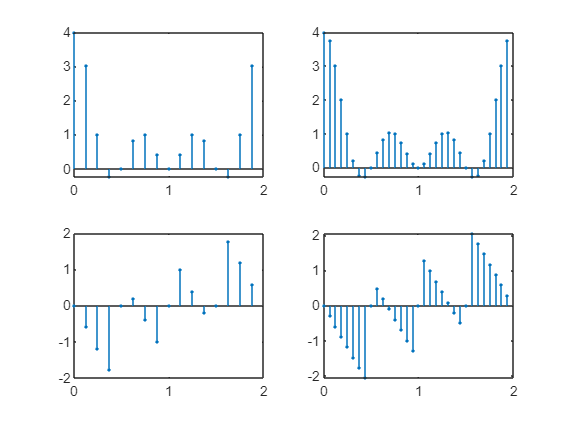

subplot(2,2,4);plot(w32,fa32);stem(w32,fa32,'.');

23

xn=[1 2 3 2 1];
%(1)
Xejw=fft(xn,1024)

Xejw =    9.0000 + 0.0000i   8.9991 - 0.1104i   8.9964 - 0.2208i   8.9919 - 0.3312i   8.9855 - 0.4414i   8.9774 - 0.5515i   8.9675 - 0.6615i   8.9558 - 0.7712i   8.9423 - 0.8807i   8.9270 - 0.9900i   8.9099 - 1.0989i   8.8911 - 1.2076i   8.8705 - 1.3158i   8.8481 - 1.4237i   8.8240 - 1.5311i   8.7981 - 1.6381i   8.7705 - 1.7446i   8.7412 - 1.8505i   8.7101 - 1.9559i   8.6774 - 2.0607i   8.6430 - 2.1649i   8.6069 - 2.2685i   8.5691 - 2.3714i   8.5297 - 2.4736i   8.4886 - 2.5750i   8.4460 - 2.6757i   8.4017 - 2.7755i   8.3558 - 2.8746i   8.3084 - 2.9728i   8.2594 - 3.0701i   8.2089 - 3.1665i   8.1568 - 3.2620i   8.1033 - 3.3565i   8.0482 - 3.4500i   7.9917 - 3.5425i   7.9338 - 3.6340i   7.8745 - 3.7243i   7.8137 - 3.8136i   7.7516 - 3.9018i   7.6881 - 3.9889i   7.6233 - 4.0747i   7.5572 - 4.1594i   7.4898 - 4.2429i   7.4211 - 4.3252i   7.3512 - 4.4061i   7.2801 - 4.4859i   7.2078 - 4.5643i   7.1344 - 4.6414i   7.0598 - 4.7172i   6.9841 - 4.7916i


%(2)
Xk32=fft(xn,32);fa32=angle(Xk32);
n32=0:length(Xk32)-1;w32=n32./16;
figure(2);
subplot(2,1,1);plot(w32,Xk32);stem(w32,Xk32,'.');

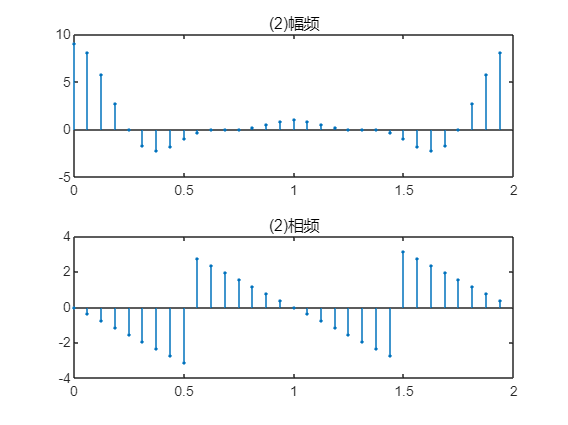

title('(2)幅频');
subplot(2,1,2);plot(w32,fa32);stem(w32,fa32,'.');
title('(2)相频');

%(3)
faejw=angle(Xejw);nejw=0:length(Xejw)-1;wejw=nejw./512;
figure(3);
subplot(2,2,1);plot(wejw,Xejw);stem(wejw,Xejw,'.');

title('(3)Xejw幅频');
subplot(2,2,3);plot(wejw,faejw);stem(wejw,faejw,'.');
title('(3)Xejw相频');
subplot(2,2,2);plot(w32,Xk32);stem(w32,Xk32,'.');

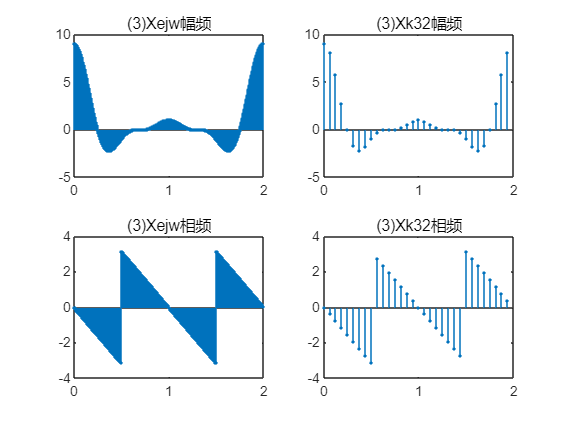

title('(3)Xk32幅频');
subplot(2,2,4);plot(w32,fa32);stem(w32,fa32,'.');
title('(3)Xk32相频');

%(4)
Xk32i=ifft(Xk32,32)

Xk32i =     1.0000    2.0000    3.0000    2.0000    1.0000    0.0000         0   -0.0000    0.0000         0   -0.0000   -0.0000         0   -0.0000         0   -0.0000         0         0         0   -0.0000   -0.0000   -0.0000         0    0.0000   -0.0000         0   -0.0000    0.0000         0    0.0000         0         0
